# Working with energy data

This live script extracts data from the energy production and demand in Denmark in the past 5 years and performs an energy balance on the possibility of offshore storage. The first part of the work is done based on simple energy balance and the second parts looks into the subsurface energy storage.

## Plotting the energy data

There is an script for plotting the energy data, that is used as shown in the following example

date1 = '2021-01-01';
date2 = '2021-01-20';
d = extract_elect_data(date1, date2);
d.HourDK = datetime(d.HourDK, 'Format', 'yyyy-MM-dd''T''HH:mm:ss');

The above script extracts the data, that is plotted by

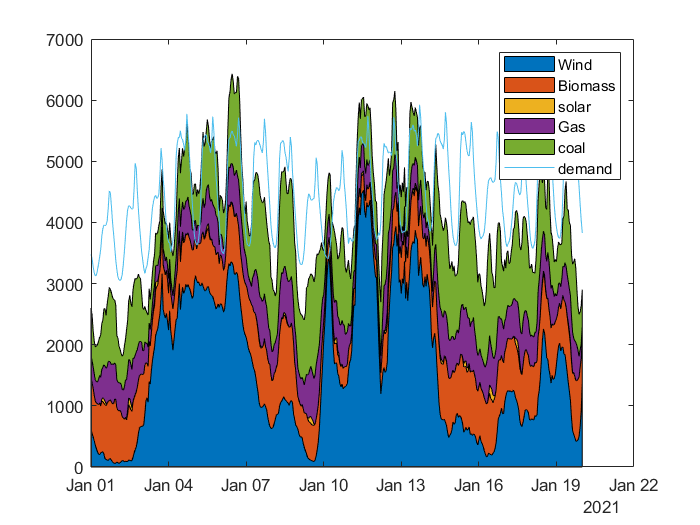

h = area(d.HourDK, [d.OnshoreWindPower+d.OffshoreWindPower d.Biomass d.SolarPower d.FossilGas d.FossilHardCoal]); 
hold on; 
plot(d.HourDK, d.TotalLoad)
legend('Wind', 'Biomass', 'solar', 'Gas', 'coal', 'demand')
hold off

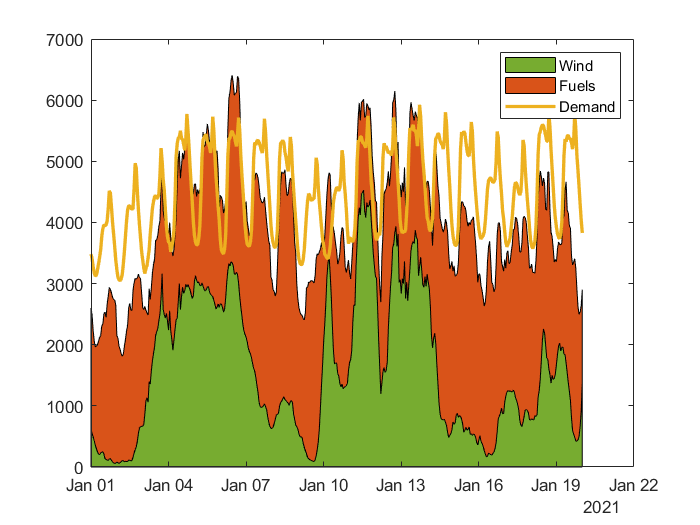


h = area(d.HourDK, [d.OnshoreWindPower+d.OffshoreWindPower d.Biomass+d.FossilGas+d.FossilHardCoal]); 
h(1).FaceColor=[0.4660 0.6740 0.1880];
hold on; 
plot(d.HourDK, d.TotalLoad, 'LineWidth', 2); 
legend('Wind', 'Fuels', 'Demand'); 
hold off

# The future energy balance

In the near future, Denmark is going to have its windfarm capacity quadruppled. This will potentially remove the fossil fuel power plants. In practice, the production is fluctuating and sometimes, there won't be enough electricity if the wind is slow. At night and during low demand periods, there will be too much electricity. The solution is to "flatten the curve". Let's have a look at the electricity demand and the quadruppled wind electricity supply:

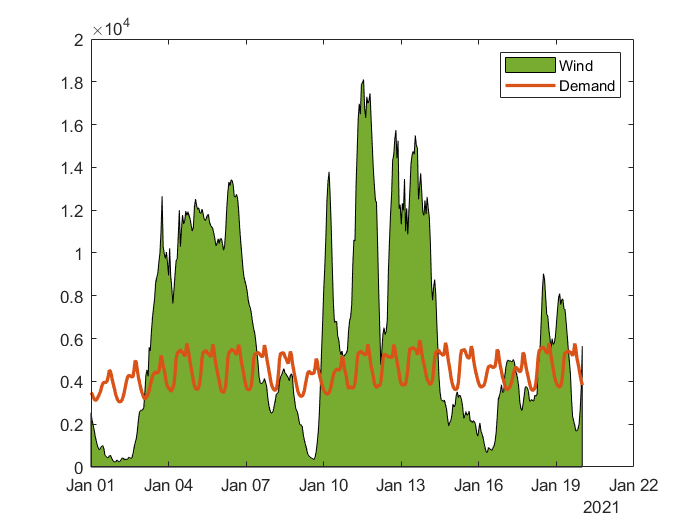

h = area(d.HourDK, 4*(d.OnshoreWindPower+d.OffshoreWindPower)); 
h(1).FaceColor=[0.4660 0.6740 0.1880];
hold on; 
plot(d.HourDK, d.TotalLoad, 'LineWidth', 2); 
legend('Wind', 'Demand'); 
hold off

Countries plan their electricity production based on "unavailabilities" and "shortages" because a pregnant lady in the delivery room cannot synchronise her due time with the time that the wind starts blowing. I chose this methaphor because it is the most amazing and scariast scene that I've seen in my life.

## The reality

In practice, the surplus electricity is going to be so cheap that the producer has to pay to get rid of it.

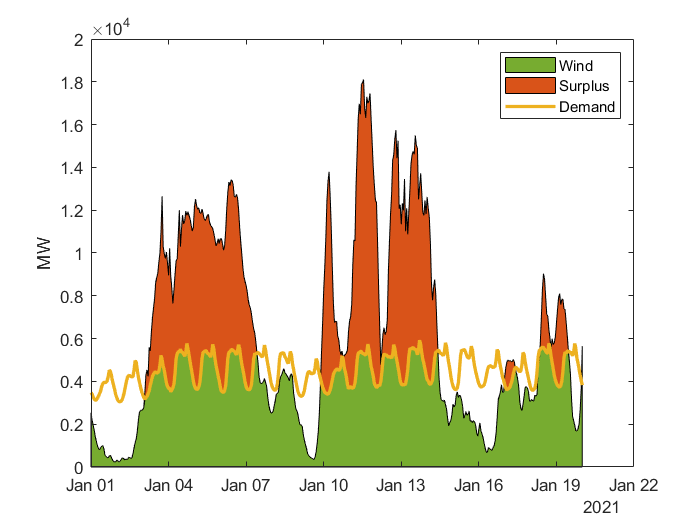

new_elec = 4*(d.OnshoreWindPower+d.OffshoreWindPower);
surplus_elec = new_elec-d.TotalLoad;
new_elec(new_elec>d.TotalLoad) = d.TotalLoad(new_elec>d.TotalLoad);
surplus_elec(surplus_elec<0) = 0;
shortage_elec = d.TotalLoad-new_elec;
h = area(d.HourDK, [new_elec surplus_elec]); 
h(1).FaceColor=[0.4660 0.6740 0.1880];
hold on; 
plot(d.HourDK, d.TotalLoad, "LineWidth", 2);
ylabel('MW')
legend('Wind', 'Surplus', 'Demand');
hold off

## How to address it?

The way to address it is to take the surplus, store it somewhere, and consume it when there is a shortage:

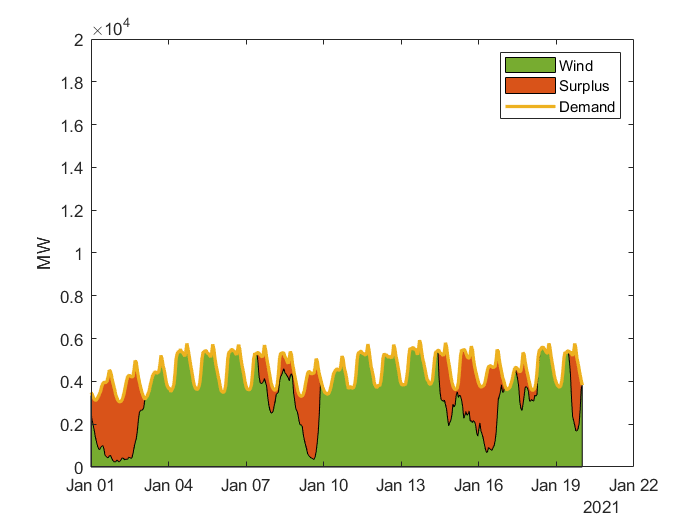

h = area(d.HourDK, [new_elec shortage_elec]);
h(1).FaceColor=[0.4660 0.6740 0.1880];
hold on; 
plot(d.HourDK, d.TotalLoad, 'LineWidth', 2);
ylabel('MW')
legend('Wind', 'Surplus', 'Demand'); 
ylim([0 2e4]);
hold off

And there might still be some extra for other applications, e.g. creating liquid fuels.

## Let's integrate

We can integrate the amount of surplus and unavailable electricity:

date_num = datenum(d.HourDK);
average_shortage = trapz(date_num, shortage_elec)/(date_num(end)-date_num(1))

average_shortage = 949.7443

average_surplus = trapz(date_num, surplus_elec)/(date_num(end)-date_num(1))

average_surplus = 2.9614e+03

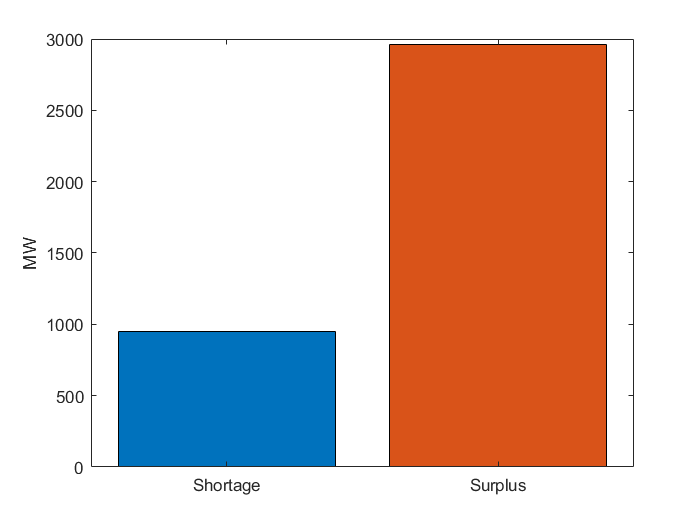

b = bar(categorical({'Surplus', 'Shortage'}), [average_surplus, average_shortage]); 
b.FaceColor = 'flat'; b.CData(2, :) = [0.8500 0.3250 0.0980]; 
ylabel('MW')

This means that only less than 30% of the surplus electricity is required to fill the gap created by the shortage of wind. There are several ways of storing the electricity by converting it to different forms of physical or chemical energy. The next question is, when the energy conversion is done, how and where the converted storable form can be kept?

# A 6-month view

The above figures only look at the month of January 2021. Let's have a look a longer period of time, e.g. six month to one year and compare the surplus and shortage. This time, naturally, I have written a function:

date_begin = '2020-05-01';
date_end = '2021-01-20';
d_long = extract_elect_data(date_begin, date_end);
